clear all, clc, close all;

fid = fopen('../FPD/data/policy.json');
raw = fread(fid); 
str = char(raw'); 
fclose(fid); 
val = jsondecode(str);

aTc = val.v1;
IPTG = val.v2;

sbioloadproject Genetic_Toggle_Switch_Simplified.sbproj

for i = 1:length(IPTG)
    trigger = strcat('time >= ', int2str((i-1)));
    evnt_IPTG = strcat('IPTG = ', num2str(IPTG(i)), '*u0');
    evnt_aTc = strcat('aTc = ', num2str(aTc(i)), '*u0');
    addevent(m1, trigger, {evnt_aTc, evnt_IPTG});
end

sim = sbiosimulate(m1);

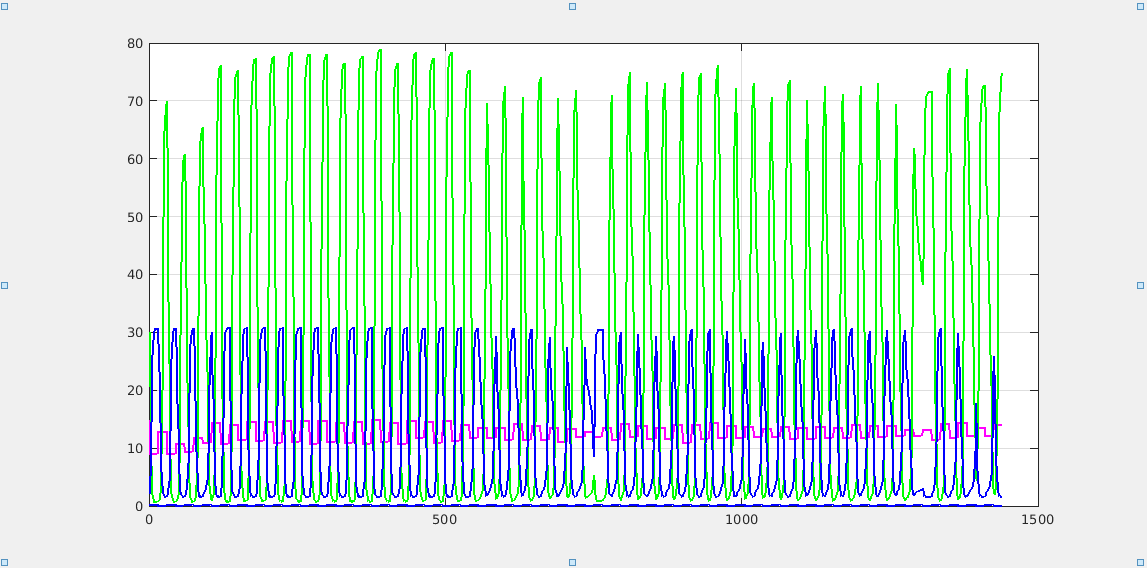

close all;
figure(1);
clf reset
plotbrowser('on');
pl = plot(sim.Time, sim.Data(:,1), 'DisplayName','IPTG');
set(pl,'linewidth',2, 'Color', 'b');
hold on
pl = plot(sim.Time, sim.Data(:,4), 'DisplayName','aTc');
set(pl,'linewidth',2, 'Color', 'm');
pl = plot(sim.Time, sim.Data(:,2), 'DisplayName','LacI');
set(pl,'linewidth',2, 'Color', 'g');
pl = plot(sim.Time, sim.Data(:,3), 'DisplayName','TetR');
set(pl,'linewidth',2, 'Color', 'b');
hold off
grid